# Batch Processing

In this livescript, we will cover ways to process multiple datasets. So far, we have only concentrated on a single dataset. How about the others? It would be cumbersome to repeat lines of code to preprocess multiple files or change the file path manually for each time (something I am guilty of when I first started learning how to code). This is why looping is very important! We can loop through multiple datasets and preprocess them at every iteration. 

## For Loops

In computer science, a **for loop** is a control flow statement for specifying iteration. It functions by running a section of code repeatedly until a certain condition has been satisfied. For MATLAB, here is the official [documentation](https://www.mathworks.com/help/matlab/ref/for.html). Let's look at a basic for loop written in MATLAB: 

%Example for loop:
for i = 5:9
    i
end

Notice the **end** of the for loop. If you forget to write end, you will get an error. Remember:** For every *****for*****, you need an end! **This applies to any if/else or while statements. Also, the **i** variable changes in value in each iteration, a total of 5 times. This is because of array (**1:5**). Change the numbers and see what i is equal in each iteration. This array can be something random. For instance if you put 5:9, then i would output 5, 6, 7, 8 ,and 9, or if you put [7,4,3,2,7], i would output 7, 4, 3, 2, and 7. There is also no requirement that you have to use the **variable i**. You can use any letter or word. Decrementing values is also possible. We will use a different variable and a decrementing array: 

for index_something = array_1
    index_something
end

That seems pretty simple. But we can complicate things with a nested for loop; that is, we can have a for loop inside of a for loop (for loop inception). Nested for loops can be useful when filling out a matrix full of values, iterating over rows and columns. As you will see later, we can use nested for loops to iterate over subjects and their multiple datasets. 

%Initializing an matrix with 20 rows and 14 columns
mat = zeros(20,14);

%We will iterate over rows:
for i = 1:size(mat,1)
    %Iterating over columns
    for j = 1:size(mat,2)
        mat(i,j) = i + j;
    end
end

%Displaying resulting matrix
mat

We can skip certain iterations with **continue**. Using continue will skip the current iteration within the for loop. This can have several uses for batch preprocessing; for instance, we can skip certain subjects if we need to process them differently. Let's look at a one example of using continue:

%Skipping any values divisible by 3; we use the modulo function to do this,
%so look at the description by typing help mod in the command window
for i = 1:17
    %Checking if value is divisible by 3
    % if it is, we skip with continue
    if mod(i,3) == 0
        continue
    end
    %displaying i
    i
end

We can also stop a for loop with **break**. This will break the for loop that it is within. The same can be 

for i = 1:3
    %Displaying i
    fprintf('i = %i\n',i); %\n is for a new line
    for j = 1:5
        %We will break the inner for loop (j loop) if i is 2
        if i == 2
            break %see how it will only skip displaying j if i is 2
        end
        %Displaying j
        fprintf('\tj = %i\n',j); %\t is for a tab
    end
end

With these concepts in mind, we can try to look at different ways to batch preprocess some data. There are multiple ways to do this. Some ways could be more efficient and faster depending on how your data is organized or named. I personally tend to prioritize readability and adaptability so that I can copy/paste the same set up for my analysis scripts (with minimal alterations) or share my scripts with other people. That is why comments are important! You want other people to understand your code, but, more importantly, you want to understand your own code if you are working on other projects. I will show you the ways I have batch preprocessed data in the past. I will show you **THREE EXAMPLES OF HOW TO BATCH PREPROCESS**.

BUT, FIRST let's define our data directories with the same pieces of code we have been using for most of these tutorials

eeglab: options file is C:\Users\enriq\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one


Retrieving plugin versions from server...
Retrieving download statistics...
Issue with retrieving statistics for extensions
EEGLAB: adding "AMICA" v1.7 (see >> help eegplugin_amica)
EEGLAB: adding "Fieldtrip-lite" v20230613 to the path
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.2 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)
EEGLAB: adding "fitTwoDipoles" v1.00 (see >> help eegplugin_fitTwoDipoles)
EEGLAB: adding "postAmicaUtility" v2.1 (see >> help eegplugin_postAmicaUtility)
EEGLAB: adding "xdfimport" v1.18 (see >> help eegplugin_xdfimport)


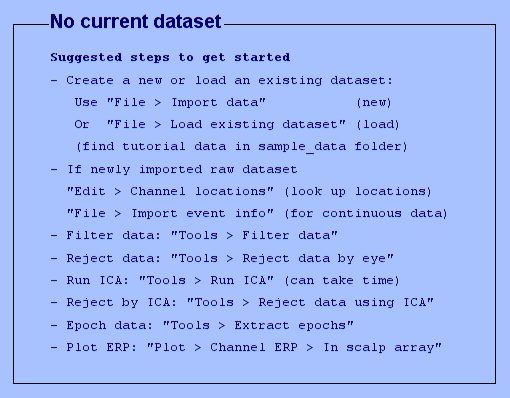

%Initializing EEGlab
eeglab;

%Directory where are data are located:
dir_data = 'data'; %Change this to where your data is

%Directory where our LSL recordings are located:
dir_xdf = fullfile(dir_data,'xdf');

%Directory where headset data are located:
dir_head = fullfile(dir_data,'headset_channel_locations');

%Directory where we will save our data:
dir_set = fullfile(dir_data,'set');

%Adding dependencies to path
addpath('dependencies')

%Channels We Want to Remove which include external channels and trigger:
rmCh_labels = {...
    'Trig1','EX1','EX2','EX3','EX4','EX5','EX6','EX7','EX8'...
    };

## 1. Indiscriminately Loading All Files

In this section, we will load in any xdf files in your data folder and preprocess them. You will see that it is **very easy** to do this. We will use a wildcard character * (asterisk) to load in all xdf files in our xdf directory. A new function we will use is **dir** which takes in the file name of the folder. The ouput of this function is a struct vector with multiple fields including the name of the file. Let's see how we use this function:

% Path/structure of your xdf folder; We use the wildcard to indicate that we
%only want xdf files. We can do this with set files or any other file
%extensions we want (e.g., '*.set' or '*.xlsx')
path_files = fullfile(dir_xdf,'*.xdf');

%Using Dir gives us a struct vector (similar to the EEG struct)
file_info = dir(path_files)

file_info = 12×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


%Storing all file names in a cell array
xdf_files = {file_info.name}

xdf_files = 1×12 cell array
    {'vrcct_p16_poststudy_condition.xdf'}    {'vrcct_p16_poststudy_postbaseline.xdf'}    {'vrcct_p16_poststudy_prebaseline.xdf'}    {'vrcct_p16_prestudy_condition.xdf'}    {'vrcct_p16_prestudy_postbaseline.xdf'}    {'vrcct_p16_prestudy_prebaseline.xdf'}    {'vrcct_p20_poststudy_condition.xdf'}    {'vrcct_p20_poststudy_postbaseline.xdf'}    {'vrcct_p20_poststudy_prebaseline.xdf'}    {'vrcct_p20_prestudy_condition.xdf'}    {'vrcct_p20_prestudy_postbaseline.xdf'}    {'vrcct_p20_prestudy_prebaseline.xdf'}


With a cell array full of our xdf file names, we can load them in using eeglab, preprocess them, and save them. 

%Looping through xdf file names

for i = 1:length(xdf_files)
    %File name for each xdf
    xdf_file = xdf_files{i};

    EEG = pop_loadxdf(fullfile(dir_xdf,xdf_file));

    % Removing non-EEG channels:
    EEG = pop_select(EEG, 'nochannel', rmCh_labels);

    %Loading in Channel information:
    EEG = pop_chanedit( ...
        EEG, ...
        'load',fullfile(dir_head,'bio_semi_64.ced'));

    %Re-centering channel locations:
    EEG = pop_chanedit( ...
        EEG, ...
        'eval','chans = pop_chancenter( chans, [],[]);');

    %With no ICA or ASR:
    EEG = preprocess_eeg( ...
        EEG, ...
        'perform_ica',false, ...
        'perform_asr',false);

    % Path for save file
    file_parts = split(xdf_file,'.');
    save_file = [file_parts{1,1},'.set'];
    EEG = pop_saveset( ...
        EEG, ...
        'filename',save_file, ...
        'filepath',dir_set, ...
        'savemode','twofiles');

end

Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...
Event resorted by increasing latencies.


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...
Event resorted by increasing latencies.


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


That was pretty easy! If all the datasets need to be processed the same, we can just use the latter piece of code. For initial preprocessing, this is probably the way to go, but further processing (like extracting sections of the EEG) may make this method more cumbersome to write if different xdf files have different sections to extract. This may be more advantageous if you have lots of datasets 

## 2. Consistent Naming Convention

If you have a very consistent dataset naming convention (as you have seen , you can use that to your advantage, looping over the variable parts your names. For instance, if you are working with the vrcct data, its naming convention is:

**vrcct_SUBJECT_STUDY_PART.xdf**

You can loop through the subject identifier, the study, and part of the experiment with a for loop. This allows you to control what you want to preprocess, and later on, you can easily modify the code to extract sections of different datasets. Therefore, it requires some nested for loops depending on your naming convention. In this case, we have a nested for loops with at minimum three layers. 

It takes a little more effort to set up as we need to define a variable to store how the datasets are named. We use the function **sprintf** on this variable to replace the latter variable parts with what we want. Let's see what I mean

% Defining our file name formatter; we will use sprintf with this
format_file = 'vrcct_%s_%s_%s.%s'; %sub,study,part,and ext placeholder

%Cell array of subject identifiers
subjects = {'p16','p20'};

%cell array of study
studies = {'prestudy','poststudy'};

%Experimental parts
parts = {'prebaseline','postbaseline','condition'};

We have defined the necessary variables to load in data. Notice the file formatter (**format_file**) in the previous block of code. We have a total of 4 placeholders that we need to define in our for loop. We will loop via subjects, studies, and parts, in that order. Note that you can iterate in a different order if you wanted to, and it may be more advantageous to do so (depending on what you want to do). 

for i = 1:length(subjects)
    %current sub id
    sub = subjects{i};

    for j = 1:length(studies)
        %Current study
        study = studies{j};

        for k = 1:length(parts)

            %Current experimental part
            part = parts{k};

            %xdf file path
            xdf_file = fullfile( ...
                dir_xdf, ...
                sprintf(format_file,sub,study,part,'xdf'));

            %Checking if file exists; if it does not, we skip
            if not(isfile(xdf_file))
                continue
            end

            %Loading in EEG
            EEG = pop_loadxdf(xdf_file);

            % Removing non-EEG channels:
            EEG = pop_select(EEG, 'nochannel', rmCh_labels);

            %Loading in Channel information:
            EEG = pop_chanedit( ...
                EEG, ...
                'load',fullfile(dir_head,'bio_semi_64.ced'));

            %Re-centering channel locations:
            EEG = pop_chanedit( ...
                EEG, ...
                'eval','chans = pop_chancenter( chans, [],[]);');

            %With no ICA or ASR:
            EEG = preprocess_eeg( ...
                EEG, ...
                'perform_ica',false, ...
                'perform_asr',false);

            %Save file path
            save_file = sprintf(format_file,sub,study,part,'set');

            %Saving EEG
            EEG = pop_saveset( ...
                EEG, ...
                'filename',save_file, ...
                'filepath',dir_set, ...
                'savemode','twofiles');


        end
    end
end

Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...
Event resorted by increasing latencies.


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...
Event resorted by increasing latencies.


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


There was a little more effort to write the code, but it is a little more readable. You control what files are being cleaned by changing the subjects, studies, and parts variables. When you want to preprocess new subjects, you can just change the variable subjects and only include new subject identifiers. It's a lot more adaptable with minimal alterations. 

## 3. Using a SpreadSheet to Load Data

A spreadsheet can be created by you to store data about each subject recordings. To load in a spreadsheet, we use the function **readtable** function that only needs the path of the spreadsheet of interest (you can load in specific sheets; read the [**documentation**](https://www.mathworks.com/help/matlab/ref/readtable.html)). You can automate the creation of this spreadsheet. In our example, we stored information in a spreadsheet called experimental_info.xlsx. In this spreadsheet, we have listed subject identifiers, study, experimental part, and xdf file name for each recording. Our plan is to iterate through interested subjects and then use boolean indexing to iterate through the xdf file name in the xdf file name column. Let's set this up and load in the spreadsheet

%Cell array of subject identifiers
subjects = {'p16','p20'};

%Loading in Experimental Information
exp_info = readtable( ...
    fullfile(dir_data,'experimental_info.xlsx'))

exp_info = 12×4 table
    subject        study        experimental_part                    xdf_file                
    _______    _____________    _________________    ________________________________________

    {'p16'}    {'prestudy' }    {'prebaseline' }     {'vrcct_p16_prestudy_prebaseline.xdf'  }
    {'p16'}    {'prestudy' }    {'postbaseline'}     {'vrcct_p16_prestudy_postbaseline.xdf' }
    {'p16'}    {'prestudy' }    {'condition'   }     {'vrcct_p16_prestudy_condition.xdf'    }
    {'p16'}    {'poststudy'}    {'prebaseline' }     {'vrcct_p16_poststudy_prebaseline.xdf' }
    {'p16'}    {'poststudy'}    {'postbaseline'}     {'vrcct_p16_poststudy_postbaseline.xdf'}
    {'p16'}    {'poststudy'}    {'condition'   }     {'vrcct_p16_poststudy_condition.xdf'   }
    {'p20'}    {'prestudy' }    {'prebaseline' }     {'vrcct_p20_prestudy_prebaseline.xdf

We have 4 columns including a column that stores the xdf file name for each recording. You can access columns by using the dot operator. If  you wanted to access the subject column, we can just use **exp_info.subject**. With this in mind, let's batch preprocess:

for i = 1:length(subjects)
    %curent subject identifier
    sub = subjects{i};

    %boolean array to find all xdf files for this subject
    ba = ismember(exp_info.subject,sub);

    %xdf files for this subject
    xdf_files = exp_info.xdf_file(ba);

    %iterating over xdf file names
    for j = 1:length(xdf_files)
        %xdf file we want to preprocess
        xdf_file = fullfile(dir_xdf,xdf_files{j});

        if not(isfile(xdf_file))
            continue
        end

        %Loading in EEG
        EEG = pop_loadxdf(xdf_file);

        % Removing non-EEG channels:
        EEG = pop_select(EEG, 'nochannel', rmCh_labels);

        %Loading in Channel information:
        EEG = pop_chanedit( ...
            EEG, ...
            'load',fullfile(dir_head,'bio_semi_64.ced'));

        %Re-centering channel locations:
        EEG = pop_chanedit( ...
            EEG, ...
            'eval','chans = pop_chancenter( chans, [],[]);');

        %With no ICA or ASR:
        EEG = preprocess_eeg( ...
            EEG, ...
            'perform_ica',false, ...
            'perform_asr',false);

        %Save file path
        file_parts = split(xdf_files{j},'.');
        save_file = [file_parts{1,1},'.set'];

        %Saving EEG
        EEG = pop_saveset( ...
            EEG, ...
            'filename',save_file, ...
            'filepath',dir_set, ...
            'savemode','twofiles');

    end
end

Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...
Event resorted by increasing latencies.


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


Now importing...

done.
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs


Removing 9 channel(s)...
Event resorted by increasing latencies.


readlocs(): 'chanedit' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 64


Radius values: 1 (mean) +/- 4.42323e-17 (std)
Note: automatically convert XYZ coordinates to spherical and polar


resampling data 250.0000 Hz
1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 
resampling event latencies...
resampling finished
pop_eegfiltnew() - performing 827 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 50] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 50.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00
Re-referencing data


Saving dataset...


This method probably takes the most effort to set up, because you have to create that additional spreadsheet full of recording information. Why would you choose this method? Let's say you have 100s of datasets with variable file names caused by multiple people recording and naming the files inconsistently. Rather than changing the names of each file, it may be more advantageous to create a spreadsheet containing not only file names, but potentially other information to use during preprocessing. For instance, you may want to store a certain event you want to insert in the EEG data before (or after) preprocessing. 

## Conclusion

These are not the only ways to batch preprocess and are the ways that I have used in the past. Each have their advantages and disadvantages. This concludes the preprocess tutorials as we have gotten up to the point where we can preprocess multiple files. No one preprocessing pipeline is universal (i.e., applicable to all projects). It depends on your research question. You may need to do a literature review to gather papers of what other people do. They often document their preprocessing method, so you can emulate that. Important resources I found very helpful are [**Makoto's preprocesing pipeline**](https://sccn.ucsd.edu/wiki/Makoto's_preprocessing_pipeline) and [**Makoto's useful EEGLAB code**](https://sccn.ucsd.edu/wiki/Makoto%27s_useful_EEGLAB_code). It documents another more complex (and computationally intensive) pipeline. There are EEGLAB plugins that attempt to standardized the preprocessing pipeline (e.g., [**PREP pipeline**](https://www.frontiersin.org/articles/10.3389/fninf.2015.00016/full)). If you join a new lab, ask them what kind of preprocessing they perform. From now on, we will concentrate on frequency analysis, epoching our data, event editing, and other topics (not in that order). 

WILL FINISH AND ADD MORE TUTORIALS (CURRENT DATE: 3/14/2023)